Consider the confound of voxel volume.

Volume: ratio of voxel volume between sites

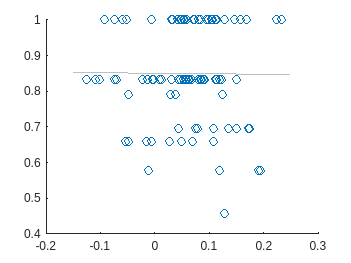

BD


                      volume 
                     ________

    spearman corr    0.027939
    p                 0.40289



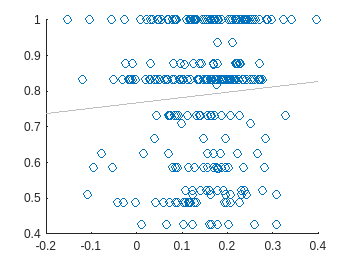

SCZ


                      volume 
                     ________

    spearman corr    0.086867
    p                 0.20664



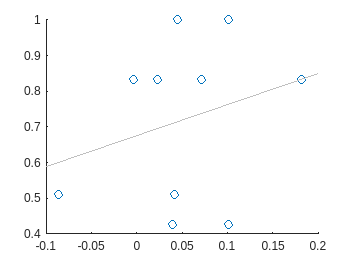

ASD


                     volume 
                     _______

    spearman corr    0.27784
    p                0.31851



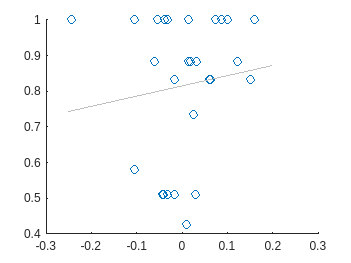

MDD


                      volume 
                     ________

    spearman corr    0.094358
    p                 0.34264



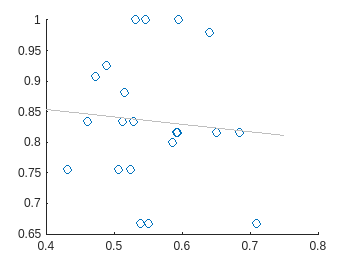

AD


                      volume 
                     ________

    spearman corr    -0.10066
    p                 0.35846



% Clear workspace and close all figures
clear all
close all

% Define parameters
iCOMBAT = 1; % Flag to indicate whether COMBAT harmonization is applied
smoothKernel = 10; % Smoothing kernel size
hemi = 'lh'; % Hemisphere (e.g., left hemisphere)
iter = 5000; % Number of iterations for statistical testing
type = 'spearman'; % Type of correlation (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on COMBAT flag
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata (scanner information)
metadata = readtable(['/projects/kg98/trangc/VBM/data/scanner_site_detailed.csv'], 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site information
load(['output/corr_zmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '_', hemi, '_all.mat'], ...
    'map', 'corDiag',  'siteList');

% Initialize variables for results
varTable = cell(nDiag, 1);
nSite = cell(nDiag, 1);

% Loop through each diagnosis
for iDiag = 1:nDiag
    % % Identify matching site information between siteList and metadata
    % [lia, lob] = ismember(siteList{iDiag}, metadata.site_string);
    % metadataFiltered = metadata(lob, :); % Filter metadata based on matched sites

    % Compute variance related to voxel volume and site information
    [varTable{iDiag}, volRatio{iDiag}, nSite{iDiag}] = cor_var_volume(metadata, diagnosisString(iDiag), corDiag{iDiag}, siteList{iDiag},iter, type);
    
    % Display results for the current diagnosis if the variance table is non-empty
    if ~isempty(varTable{iDiag})
        disp(char(diagnosisString(iDiag)));
        disp(varTable{iDiag});
        disp(' ');
        disp(' ');
    end
end


% Suppress warnings related to the last operation
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.


% Save the results to a .mat file
save('output/confound_vol.mat', 'varTable','volRatio', 'nSite');
